# Notebook 4: Spectral Identification

                Cross-spectrums would provide the ability to detect the presence of signals within a data set based on the energy of shared frequencies within the two signals. Cross-spectral analysis could be done using the KCC in the forms of the Cross-spectrum and the cross-time-frequency-distributions. This could boost signal detection within large amounts of colored noise using the KCC. The two different parts of the exploration will be a cross-spectral analysis using a fourier transform, and then a TFD of a specific flavor will be used to have a spectrographical analysis of the system. All will use the same kernel which will be the Cubic Kernel for the non-linear transformatory nature. 

## Generating Signals

% --Setup
    clear; clc; format compact; close all; 
    cd("/home/samkramer/Desktop/Engineering/Chirp Detection Algorithm/MAT Notebooks")

% --Declare Basic Signal

    % --Signal Parameters
        T = 1;              % Signal Period T (s)
        fs = 10000;         % Sample Rate (Hz)
        t = 0:1/fs:T;
        f = 1000*2*pi;        % Frequency (Hz)

    % --Create signal
        amplitude = 0.25;
        envelope = amplitude.* sin(pi*t);
        ref_signal = envelope .* sin(f*t);

% --Making Chirp Signals
    [white_signal, brown_signal, ref_chirp, ref_chirp_long, time] = generate_signals(2000, 2000);

White signal SNR is 33.812, and Brownian Signal SNR is 9.976

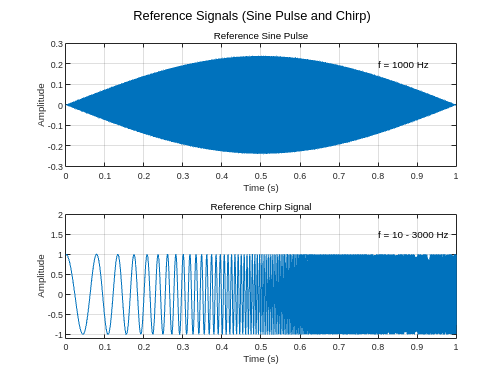

% --Zero Pad signals
    ref_signal_long = zero_pad(brown_signal, ref_signal);

% --Plotting signals
    figure()
    subplot(2,1,1)
    plot(t, ref_signal)
        grid on
        hold on
        subtitle('Reference Sine Pulse')
        xlabel('Time (s)')
        ylabel('Amplitude')
        text(0.8, 0.2, "f = 1000 Hz")

    subplot(2,1,2)
    plot(t, ref_chirp)
        subtitle('Reference Chirp Signal')
        ylim([-1.1 2])
        text(0.8, 1.5, "f = 10 - 3000 Hz")
        ylabel('Amplitude')
        xlabel('Time (s)')
        sgtitle('Reference Signals (Sine Pulse and Chirp)')
        hold on
        grid on

## Spectral Estimation with Autospectral Analysis

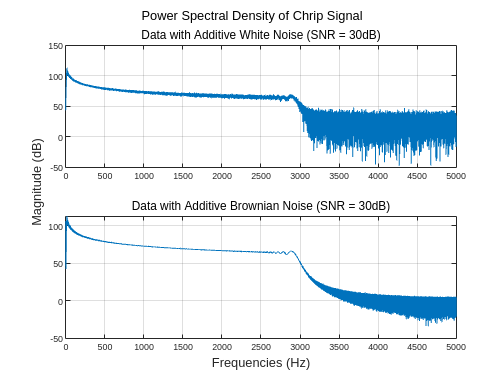

% --Taking FFT of signals
    white_signal_f = fft(white_signal);
    brown_signal_f = fft(brown_signal);

    frequencies = (1/max(time)).*(0:length(ref_chirp_long)-1);

% --Taking Autospectrum of signals
    a_spectrum_white = white_signal_f .* conj(white_signal_f);
    a_spectrum_white = abs(a_spectrum_white);
    a_spectrum_white = mag2db(a_spectrum_white);

    a_spectrum_brown = brown_signal_f .* conj(brown_signal_f);
    a_spectrum_brown = abs(a_spectrum_brown);
    a_spectrum_brown = mag2db(a_spectrum_brown);

% --Plotting
    fig = figure();
    subplot(2,1,1)
    plot(frequencies, a_spectrum_white)
        hold on
        grid on
        sgtitle('Power Spectral Density of Chrip Signal','FontSize',13)
        subtitle('Data with Additive White Noise (SNR = 30dB)','FontSize',12)
        xlim([0 5000])

    subplot(2,1,2)
    plot(frequencies, a_spectrum_brown)
        hold on
        grid on
        subtitle('Data with Additive Brownian Noise (SNR = 30dB)','FontSize',12)
        xlim([0 5000])

        % --Give common xlabel, ylabel and title to your figure
            han=axes(fig,'visible','off'); 
            han.Title.Visible='on';
            han.XLabel.Visible='on';
            han.YLabel.Visible='on';
            ylabel(han,'Magnitude (dB)','FontSize',13)
            xlabel('Frequencies (Hz)','FontSize',13)

## PSD using Kernelized Variation

The kernelized PSD is going to remain the same as the PSD however a kernelized version of the PSD MUST preserve the frequency content of the signal, This is to ensure that the PSD is accurate. This is a limitation of the kernelized version and therefore the kernel selection must be chosen carefully. 

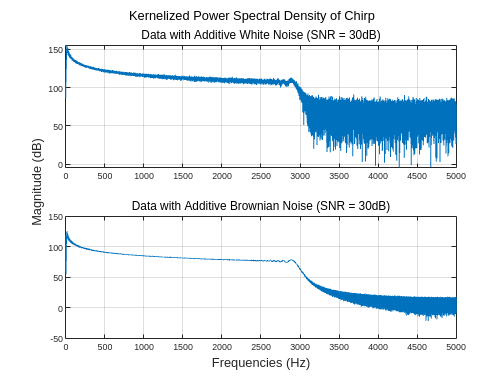

% --Finding Kernels
    k_brownian = (brown_signal + brown_signal);
    k_white = (white_signal + white_signal);

    k_brownian_f = fft(k_brownian);
    k_white_f = fft(k_white);

% --Finding kPSD
    x_spectrum_white = k_white_f .* conj(k_white_f);
    x_spectrum_white = abs(x_spectrum_white);
    x_spectrum_white = mag2db(x_spectrum_white);

    x_spectrum_brown = k_brownian_f .* conj(k_brownian_f);
    x_spectrum_brown = abs(x_spectrum_brown);
    x_spectrum_brown = mag2db(x_spectrum_brown);

% --Plot
    fig = figure();
    subplot(2,1,1)
    plot(frequencies, x_spectrum_white)
        hold on
        grid on
        sgtitle('Kernelized Power Spectral Density of Chirp')
        subtitle('Data with Additive White Noise (SNR = 30dB)','FontSize',12)
        xlim([0 5000])

    subplot(2,1,2)
    plot(frequencies, x_spectrum_brown)
        hold on
        grid on
        subtitle('Data with Additive Brownian Noise (SNR = 30dB)','FontSize',12)
        xlim([0 5000])

        % --Give common xlabel, ylabel and title to your figure
            han=axes(fig,'visible','off'); 
            han.Title.Visible='on';
            han.XLabel.Visible='on';
            han.YLabel.Visible='on';
            ylabel(han,'Magnitude (dB)','FontSize',13)
            xlabel('Frequencies (Hz)','FontSize',13)

## Spectral Estimation with Cross-Spectrums

This is meant to be a reference for the changes within the spectral estimations. This section will be the canonical cross-spectrum.

For these simulations, the sinusoidal pulse will be used to check against both signals with the chirp present. The chirps have a component where the signals have the same frequencies so there should be a peak at the shared frequency of 1 kHz.


$$\hat{S}_{xy} = \{\hat{x}\odot \hat{y} ^*\}$$


This is the formula for the cross-spectrum for frequency identification of a signal. 

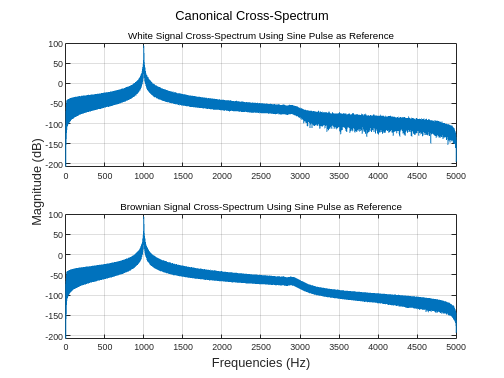

% --Creating the cross spectrums in canonical format
    ref_signal_f = fft(ref_signal_long);
    ref_chirp_f = fft(ref_chirp_long);

% --Creating the cross-spectrums
    x_spectrum_white = white_signal_f .* conj(ref_signal_f);
    x_spectrum_white = abs(x_spectrum_white);
    x_spectrum_white = mag2db(x_spectrum_white);

    x_spectrum_brown = brown_signal_f .* conj(ref_signal_f);
    x_spectrum_brown = abs(x_spectrum_brown);
    x_spectrum_brown = mag2db(x_spectrum_brown);

% --Plot
    fig = figure();
    subplot(2,1,1)
    plot(frequencies, x_spectrum_white)
        hold on
        grid on
        sgtitle('Canonical Cross-Spectrum')
        subtitle('White Signal Cross-Spectrum Using Sine Pulse as Reference')
        xlim([0 5000])

    subplot(2,1,2)
    plot(frequencies, x_spectrum_brown)
        hold on
        grid on
        subtitle('Brownian Signal Cross-Spectrum Using Sine Pulse as Reference')
        xlim([0 5000])

        % --Give common xlabel, ylabel and title to your figure
            han=axes(fig,'visible','off'); 
            han.Title.Visible='on';
            han.XLabel.Visible='on';
            han.YLabel.Visible='on';
            ylabel(han,'Magnitude (dB)','FontSize',13)
            xlabel('Frequencies (Hz)','FontSize',13)

## Spectral Estimation with Kernel Cross-Spectrum

This is the section that defines the kernel cross-spectrum that is used to estimate frequencies present in the signal. This can help with signal detection by checking data against a reference and if there is a spike at a shared frequency then there is signal present.

For these calculations the same references will be used as above.

The derivation for this goes a bit differently than the kernel cross correlation where the two parts are kernelized. This leverages the kernel of the data and the reference, and the reference is non-kernelized. This is shown below:


$$\hat{S}_{xy} = \{\hat{K}_T(x,x) \odot \hat{y} ^*\}$$


notice there is a difference between the KXCORR() and how the kernel function is the kernel of both x and y. The reference, y is not kernelized and remains the fourier transfer of the original reference signal.

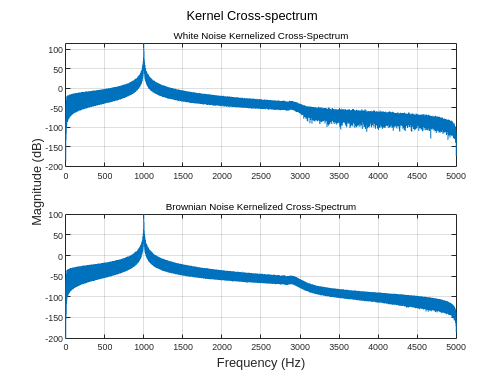

% --Finding cross-spectrums
    x_white_f = k_white_f .* conj(ref_signal_f);
    x_white_f = abs(x_white_f);
    x_white_f = mag2db(x_white_f);

    x_brownian_f = k_brownian_f .* conj(ref_signal_f);
    x_brownian_f = abs(x_brownian_f);
    x_brownian_f = mag2db(x_brownian_f);

% --Plotting cross-spectrums
    fig = figure();
    subplot(2,1,1)
    plot(frequencies, x_white_f)
        hold on
        grid on
        xlim([0 5000])
        subtitle('White Noise Kernelized Cross-Spectrum')
        sgtitle('Kernel Cross-spectrum')

    subplot(2,1,2)
    plot(frequencies, x_brownian_f)
        hold on
        grid on
        xlim([0 5000])
        subtitle('Brownian Noise Kernelized Cross-Spectrum')
        
        % --Give common xlabel, ylabel and title to your figure
            han=axes(fig,'visible','off'); 
            han.Title.Visible='on';
            han.XLabel.Visible='on';
            han.YLabel.Visible='on';
            ylabel(han,'Magnitude (dB)','FontSize',13)
            xlabel('Frequency (Hz)','FontSize',13)

This resembles the regular, non-kernelized versions of the cross-spectrums that were derived above in previous section. There is a key difference in the derivation for these than the KXCORR function. This is noted above in the explanation and derivation part before the code. 